clc
clear all

fs = 48000

fs = 48000

load("interpolated_mat_files\DOA_interpolated.mat")
P_pos = cell2mat(struct2cell(load('interpolated_mat_files\P_pos_interpolated.mat')));
P_neg = cell2mat(struct2cell(load('interpolated_mat_files\P_neg_interpolated.mat')));
P = cell2mat(struct2cell(load('interpolated_mat_files\P_interpolated.mat')));

DOA_inter{1,1} = DOA_interpolated(1:length(P),:);
P_inter{1,1} = P(1:length(P));

DOA_pos_inter{1,1} = DOA_interpolated(1:length(P_pos),:);
P_pos_inter{1,1} = P_pos(1:length(P_pos));

DOA_neg_inter{1,1} = DOA_interpolated(1:length(P_neg),:);
P_neg_inter{1,1} = P_neg(1:length(P_neg));

% original datapoint
load("rt40_mat_files\DOA_rt40.mat")
load("rt40_mat_files\pressure_rt40.mat")

DOA_first{1,1} = DOA{1,1};
P_first{1,1} = P{1,1};
DOA_original{1,1} = DOA{2,1};
P_original{1,1} = P{2,1};
DOA_third{1,1} = DOA{3,1};
P_third{1,1} = P{3,1};

a = createSDMStruct('DefaultArray','GRASVI50','fs',fs,'winLen',15);

User-defined SDM Settings are used :
           fs: 48000
            c: 345
       winLen: 15
    parFrames: 8192
    showArray: 0
      micLocs: [6×3 double]



v = createVisualizationStruct('DefaultRoom','LargeRoom',...
    'name','ESAT STADIUS Lab','fs',fs,'t',[2 5 10 20 50 100 200 2000]);

createVisualizationStruct : User-defined visualization settings are used :
              fs: 48000
           plane: 'lateral'
             DOI: 'forward'
       plotStyle: 'line'
            name: 'ESAT STADIUS Lab'
             res: 1
               t: [2 5 10 20 50 100 200 2000]
          colors: [8×3 double]
       dBSpacing: 6
      DOASpacing: 30
      dBDynamics: 45
       linewidth: [1 1 1 1 1 1 1 1]
        showGrid: 1
    smoothMethod: 'average'
       smoothRes: 3



% For visualization purposes, set the text interpreter to latex
set(0,'DefaultTextInterpreter','latex')
parameterVisualization(P_inter, v);

Started visualization of parameters.


Ended visualization of parameters in 0.76345 seconds.


Started visualization of parameters.


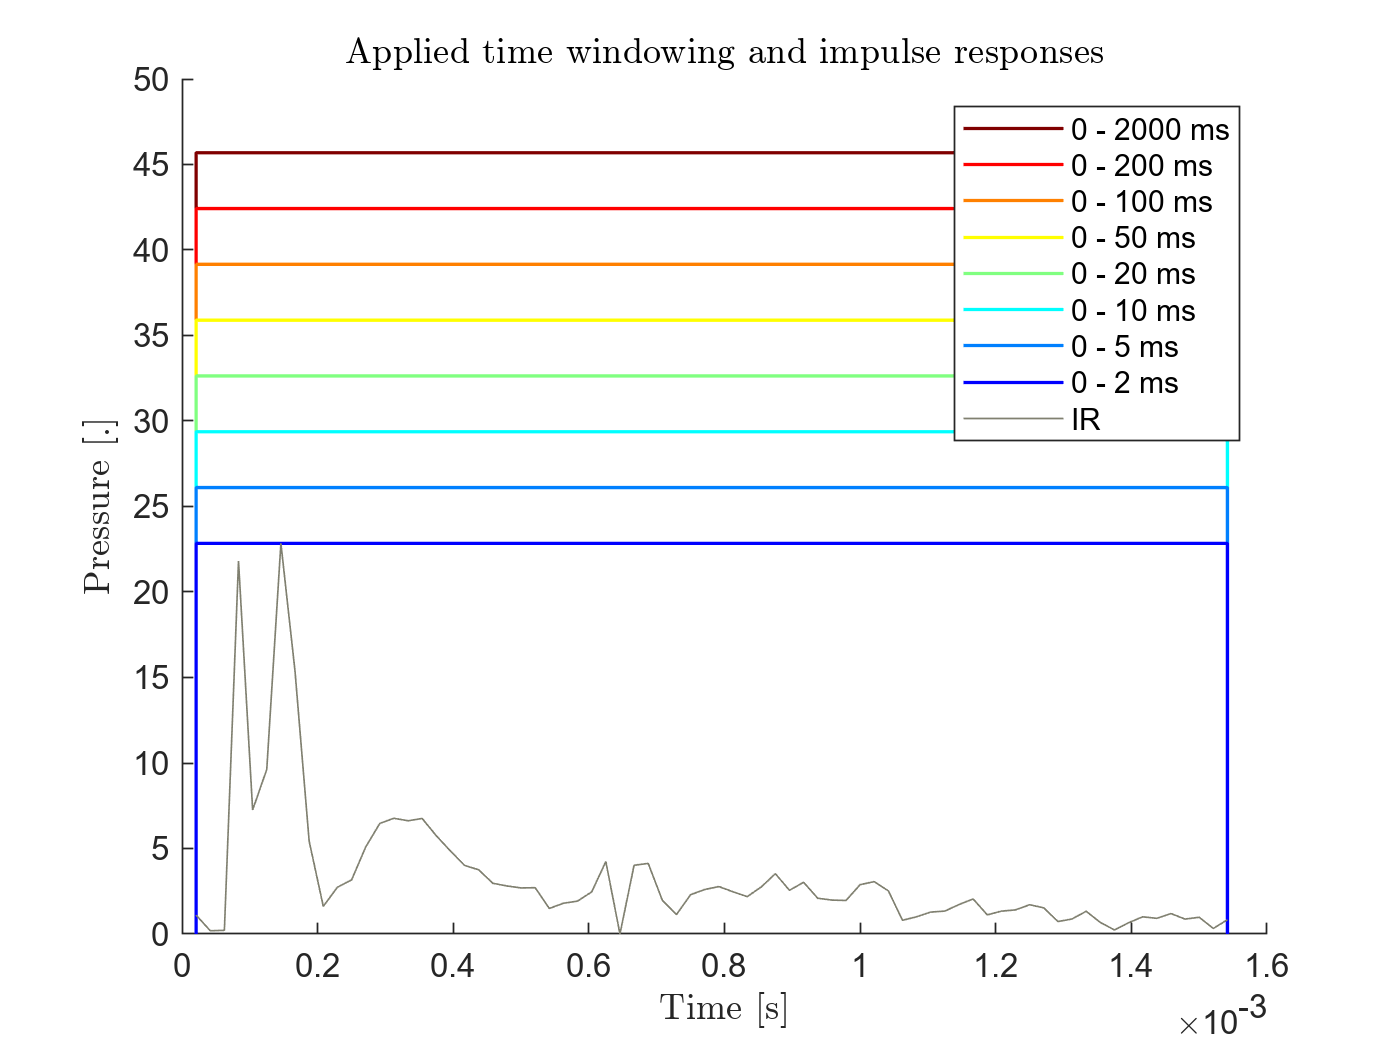

Ended visualization of parameters in 0.32494 seconds.


parameterVisualization(P_pos_inter, v);

Started visualization of parameters.


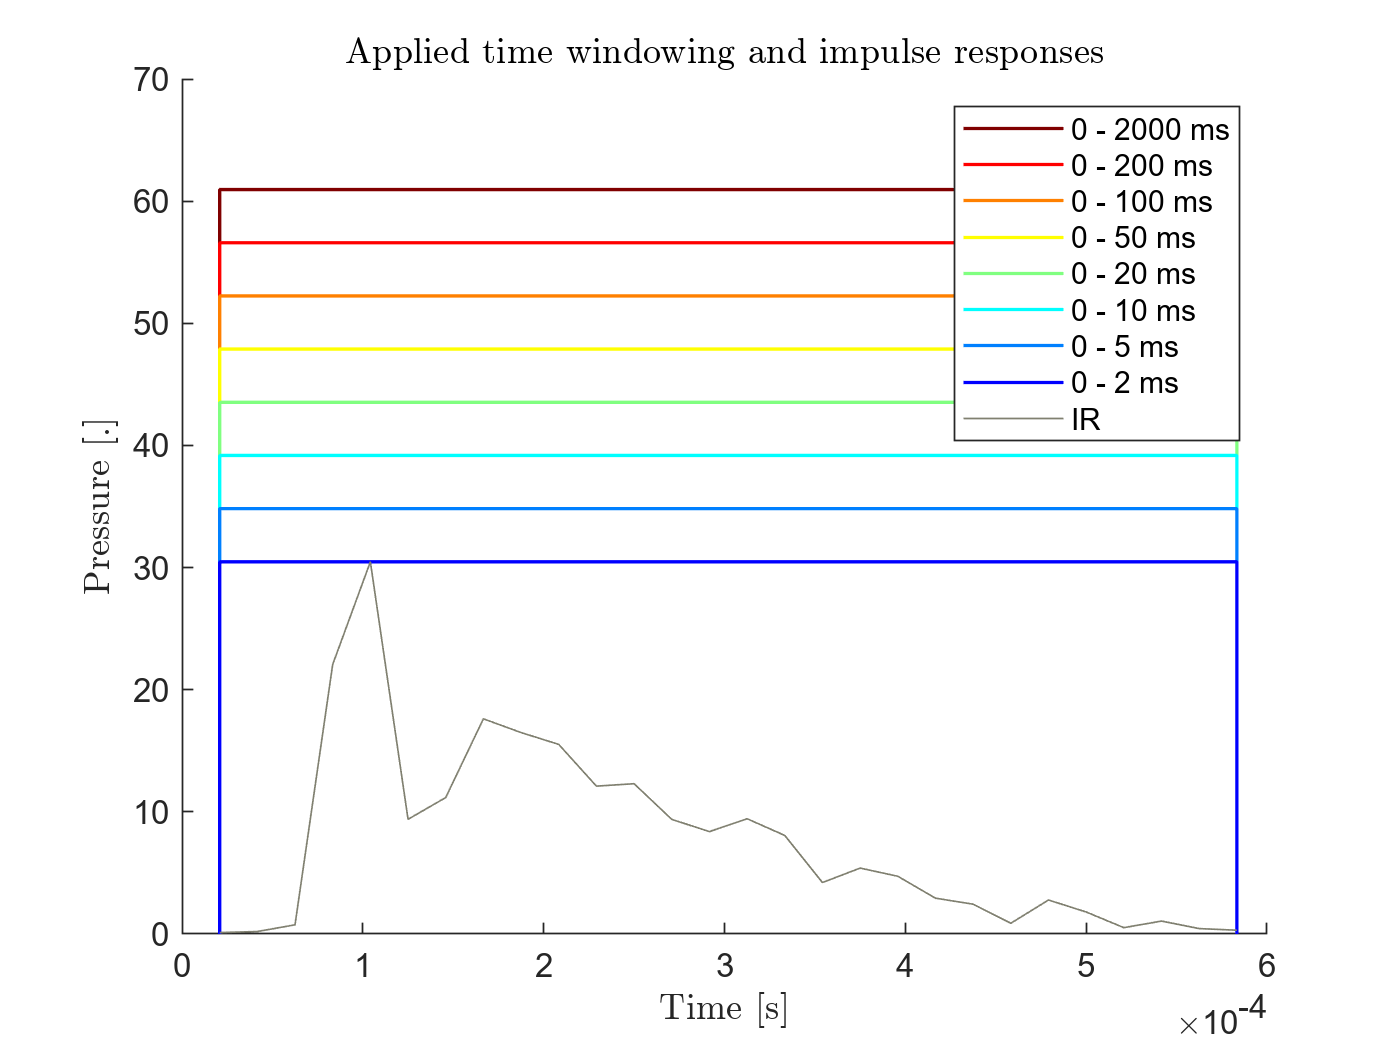

Ended visualization of parameters in 0.23221 seconds.


parameterVisualization(P_neg_inter, v);

Started visualization of parameters.


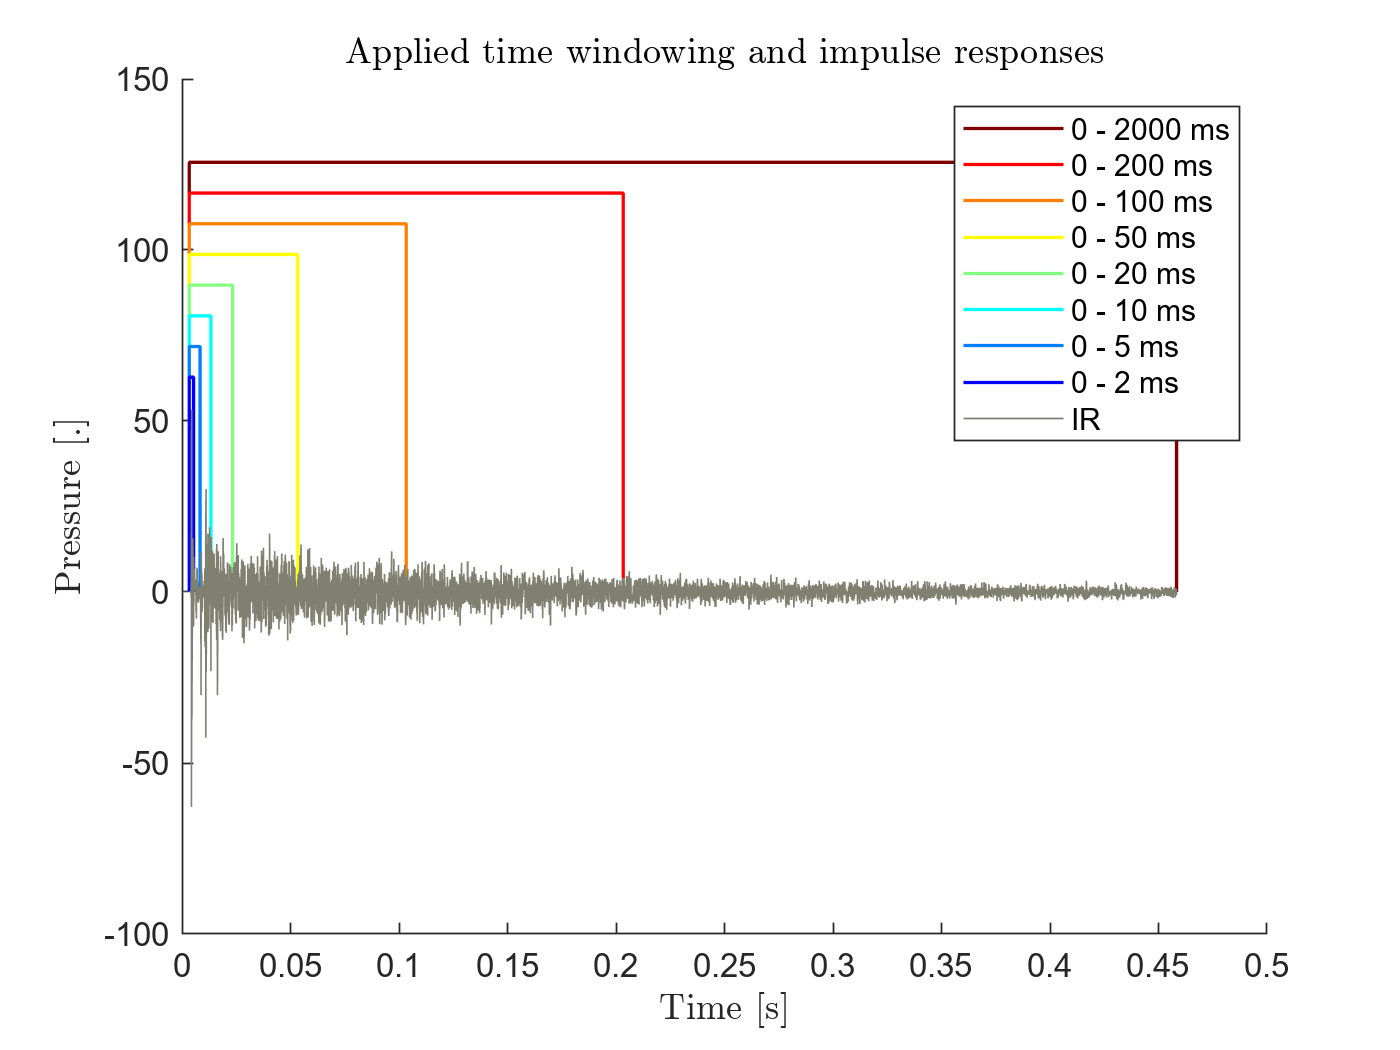

Ended visualization of parameters in 0.15441 seconds.


parameterVisualization(P_original, v);

Started time-frequency visualization.


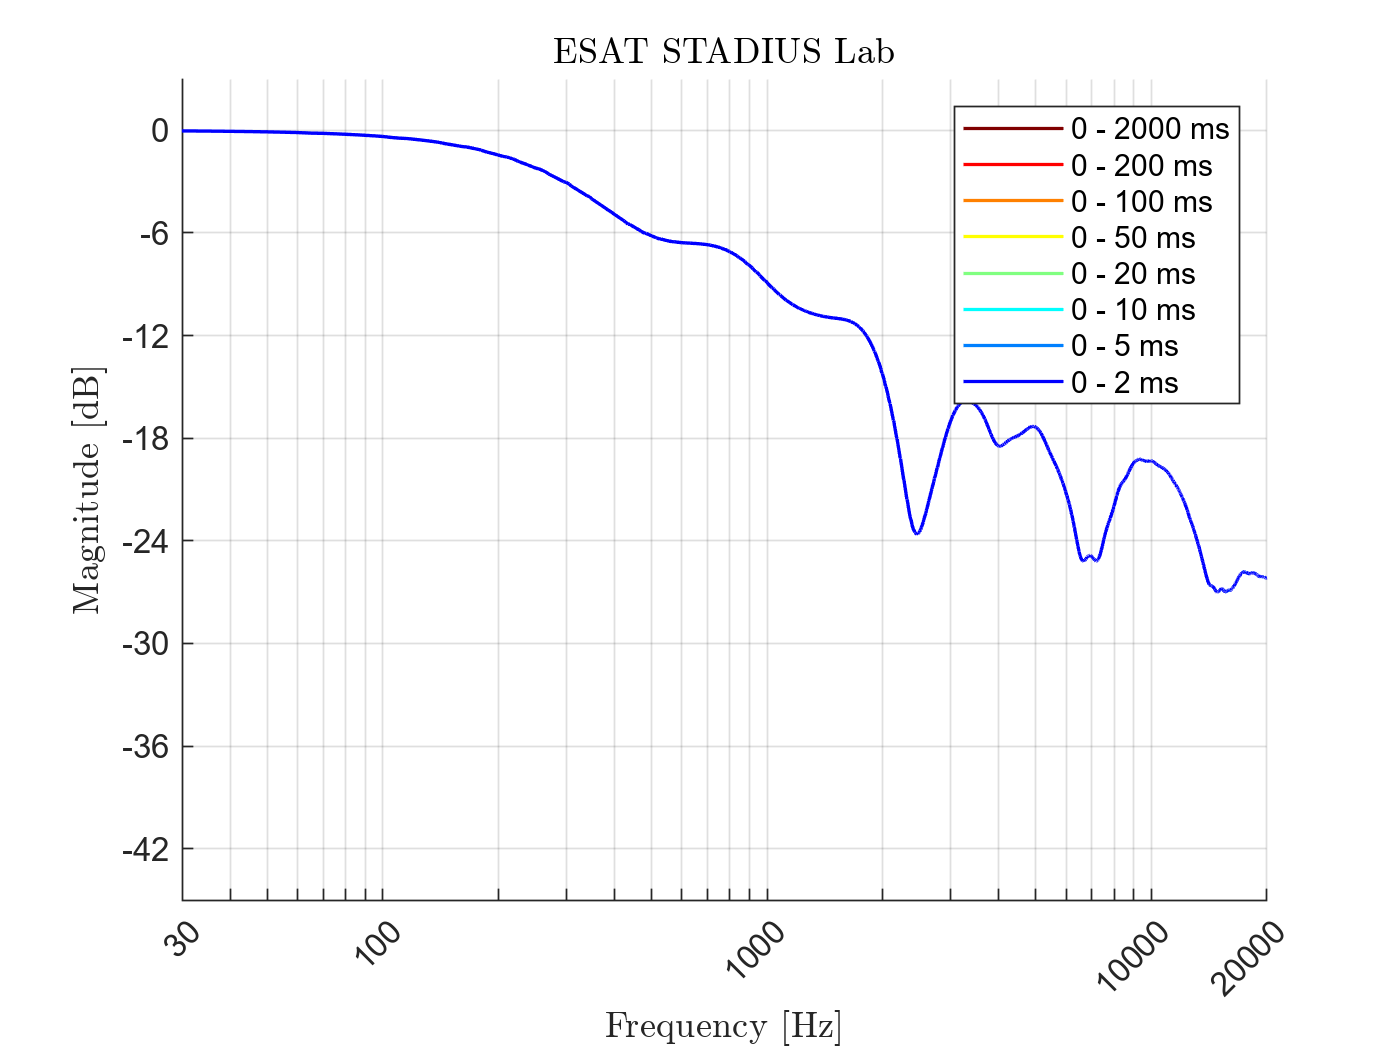

Ended time-frequency visualization in 0.81897 seconds.


timeFrequencyVisualization(P_inter, v);

Started time-frequency visualization.


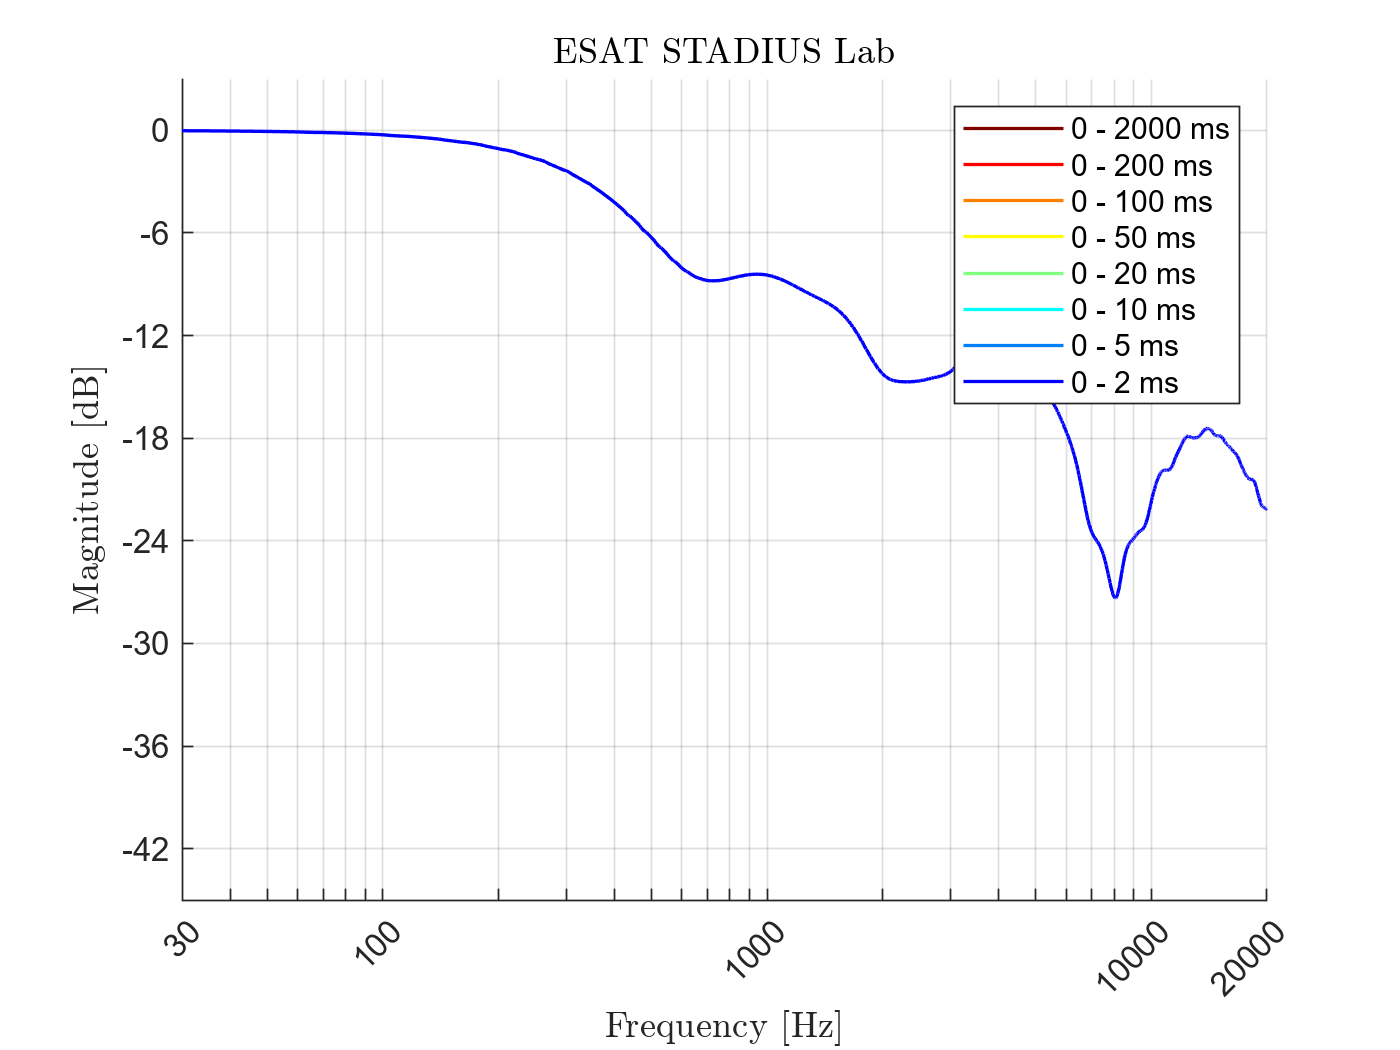

Ended time-frequency visualization in 0.45692 seconds.


timeFrequencyVisualization(P_pos_inter, v);

Started time-frequency visualization.


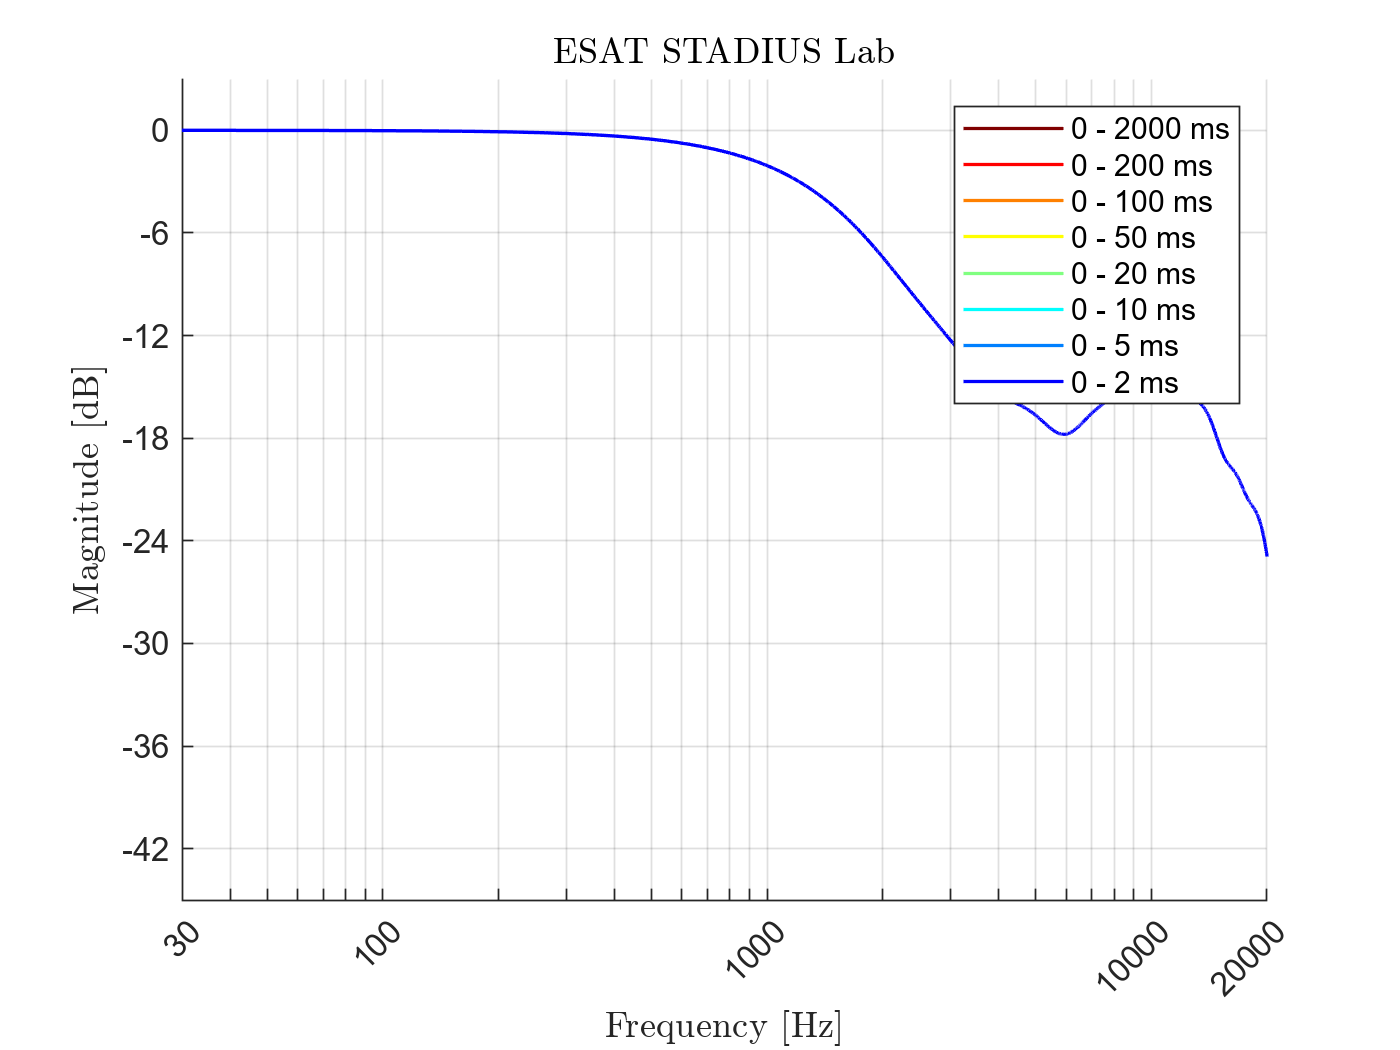

Ended time-frequency visualization in 0.43996 seconds.


timeFrequencyVisualization(P_neg_inter, v);

Started time-frequency visualization.


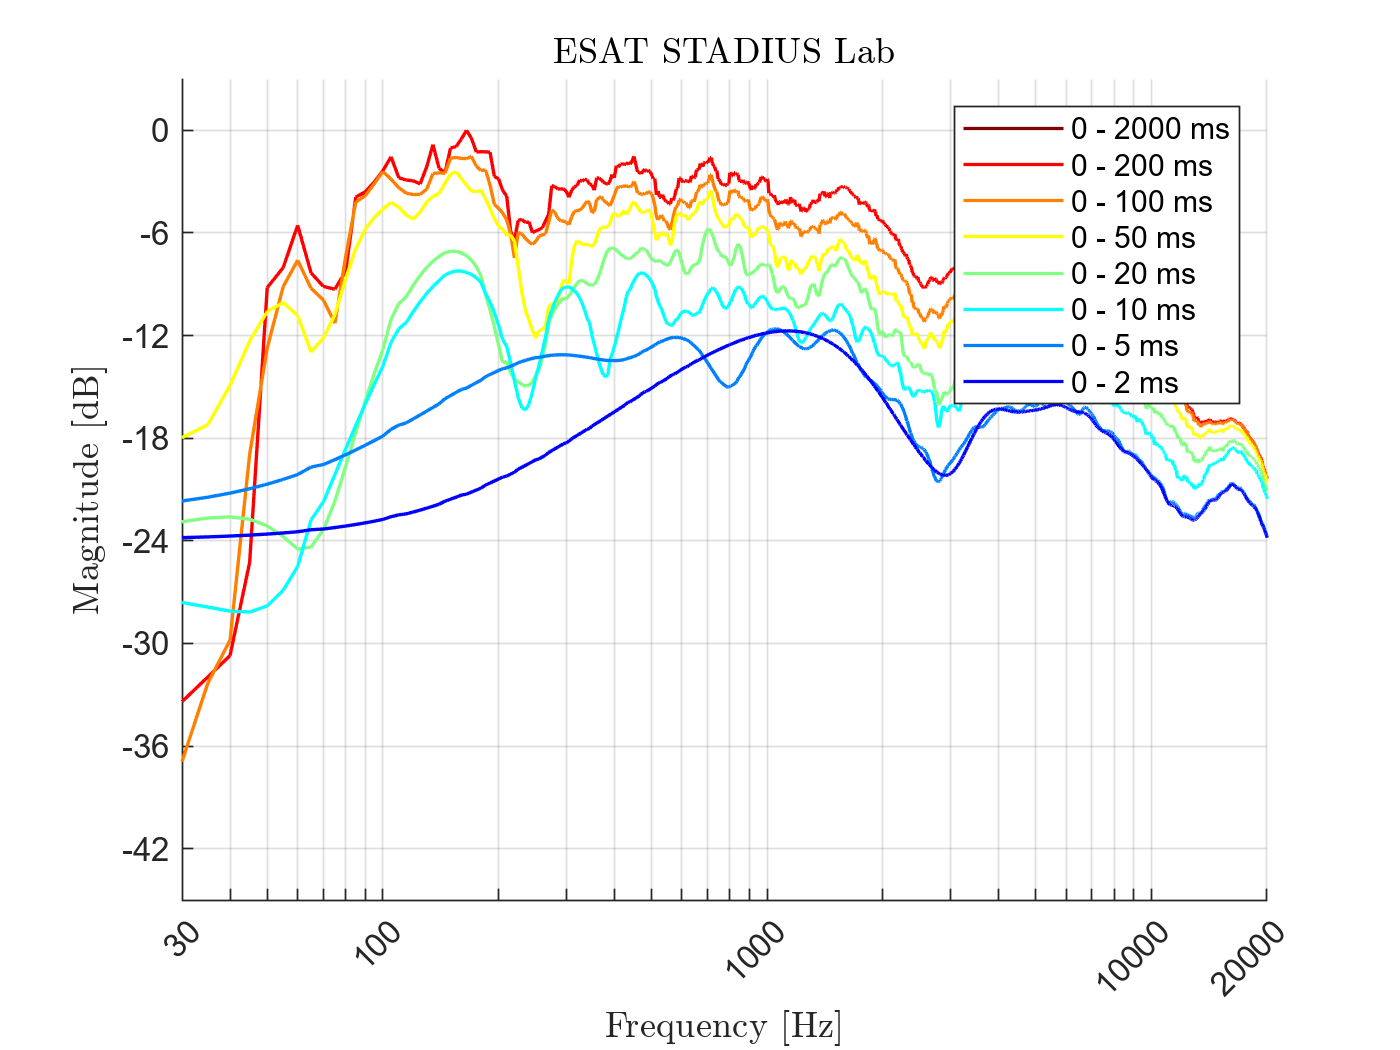

Ended time-frequency visualization in 0.44575 seconds.


timeFrequencyVisualization(P_original, v);

Started spatio-temporal visualization.


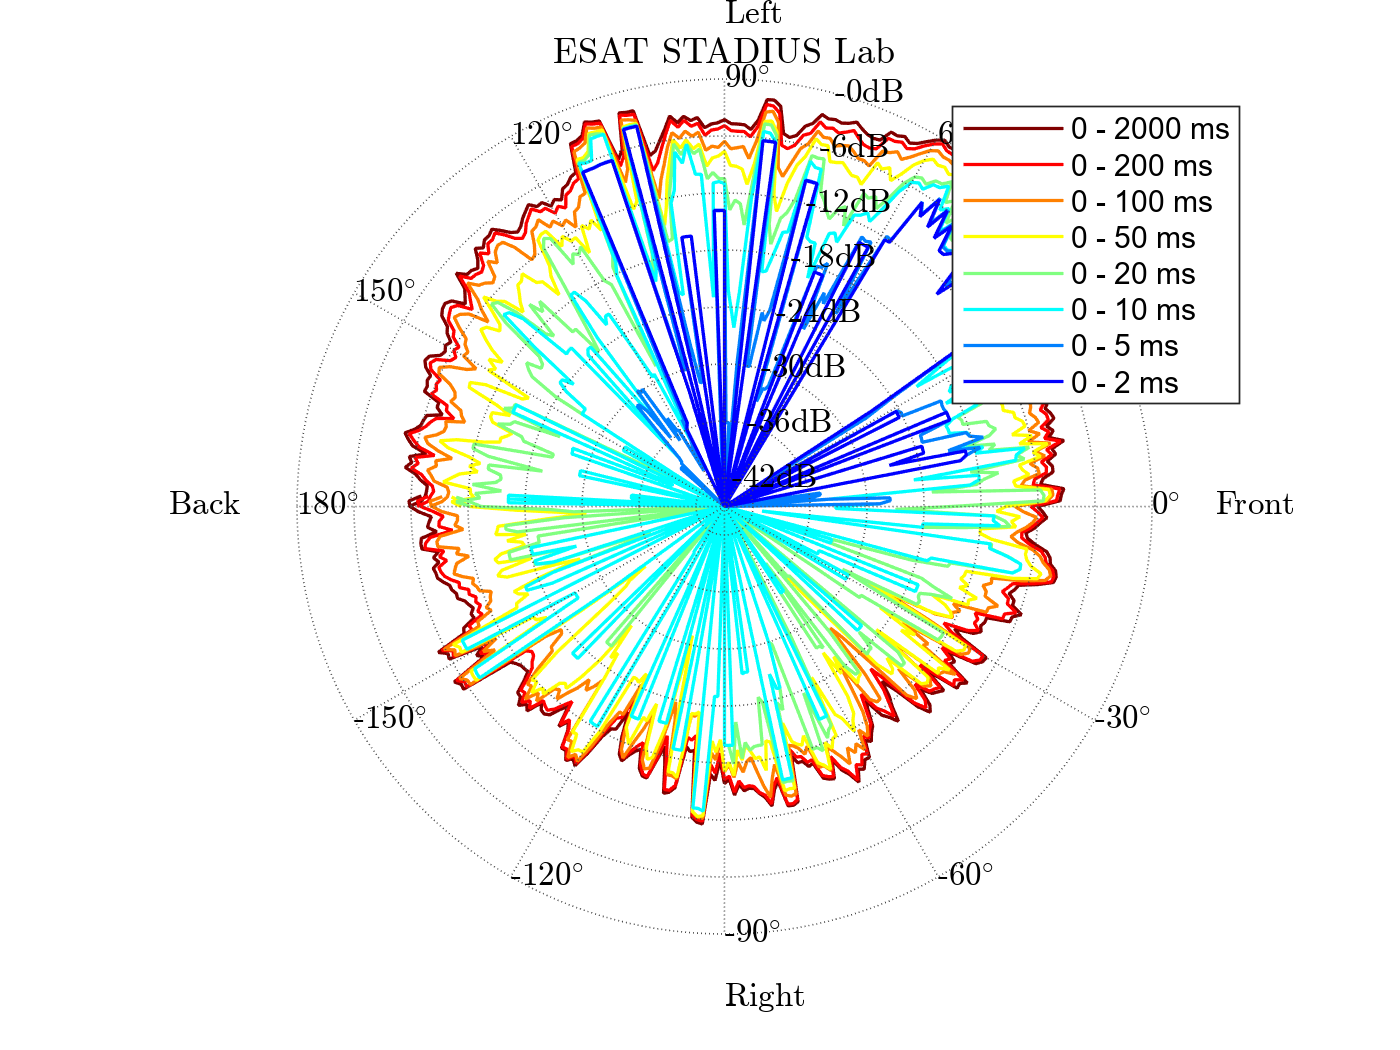

Ended spatio-temporal visualization in 0.92882 seconds.


ans = -106

v.plane = 'lateral';
% First measurement
spatioTemporalVisualization(P_first, DOA_first, v)

Started spatio-temporal visualization.


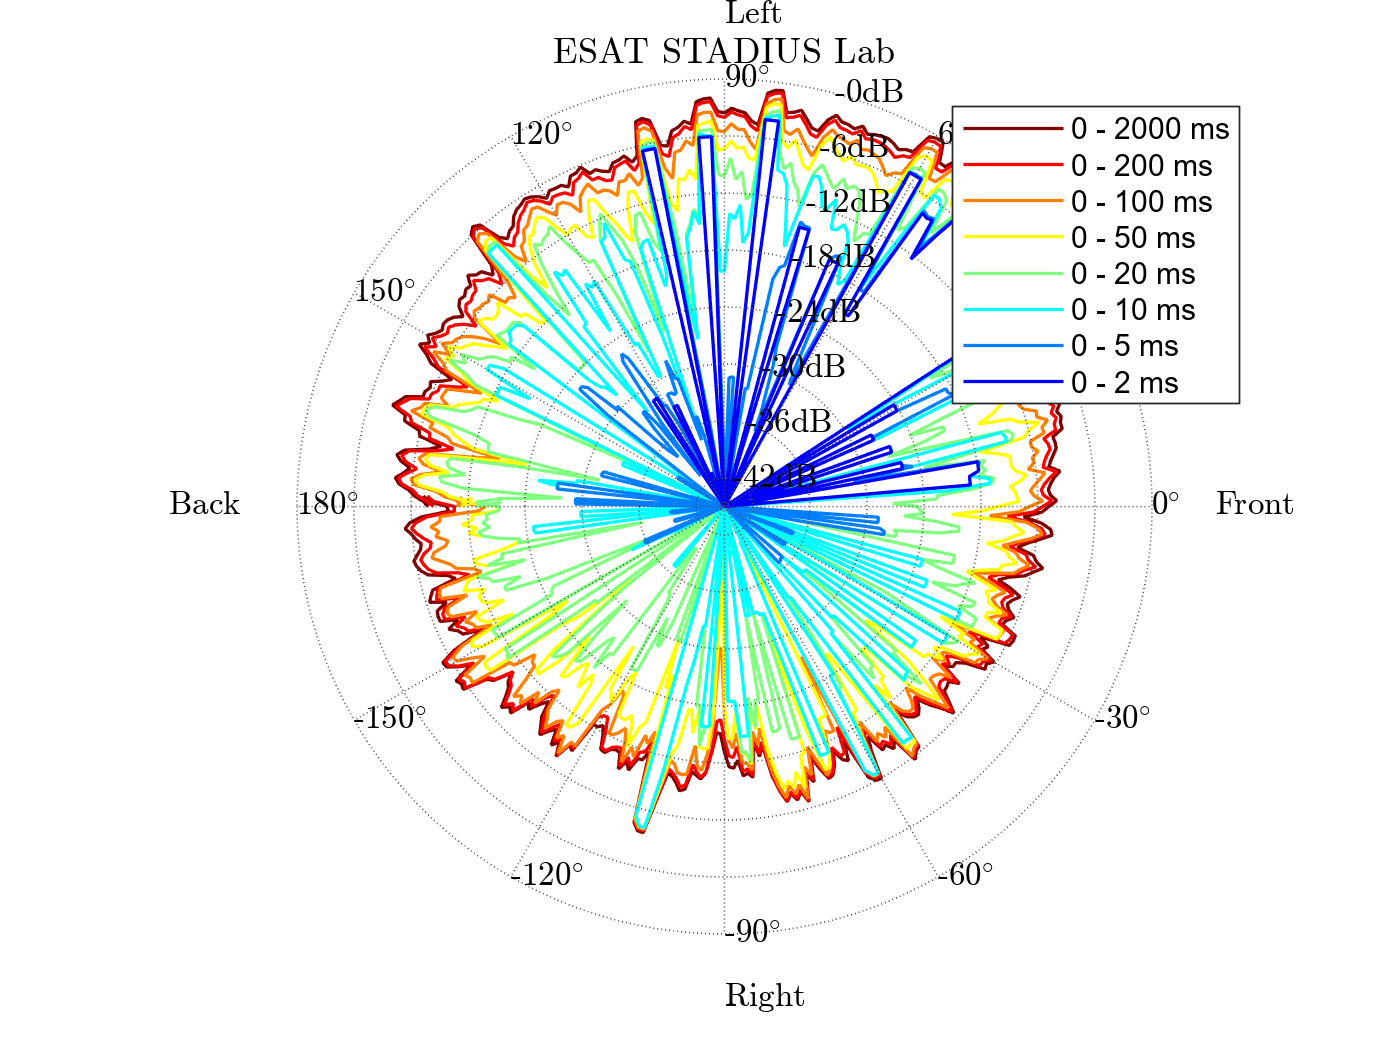

Ended spatio-temporal visualization in 0.57824 seconds.


ans = -83

% Original second measurement
spatioTemporalVisualization(P_original, DOA_original, v)

Started spatio-temporal visualization.


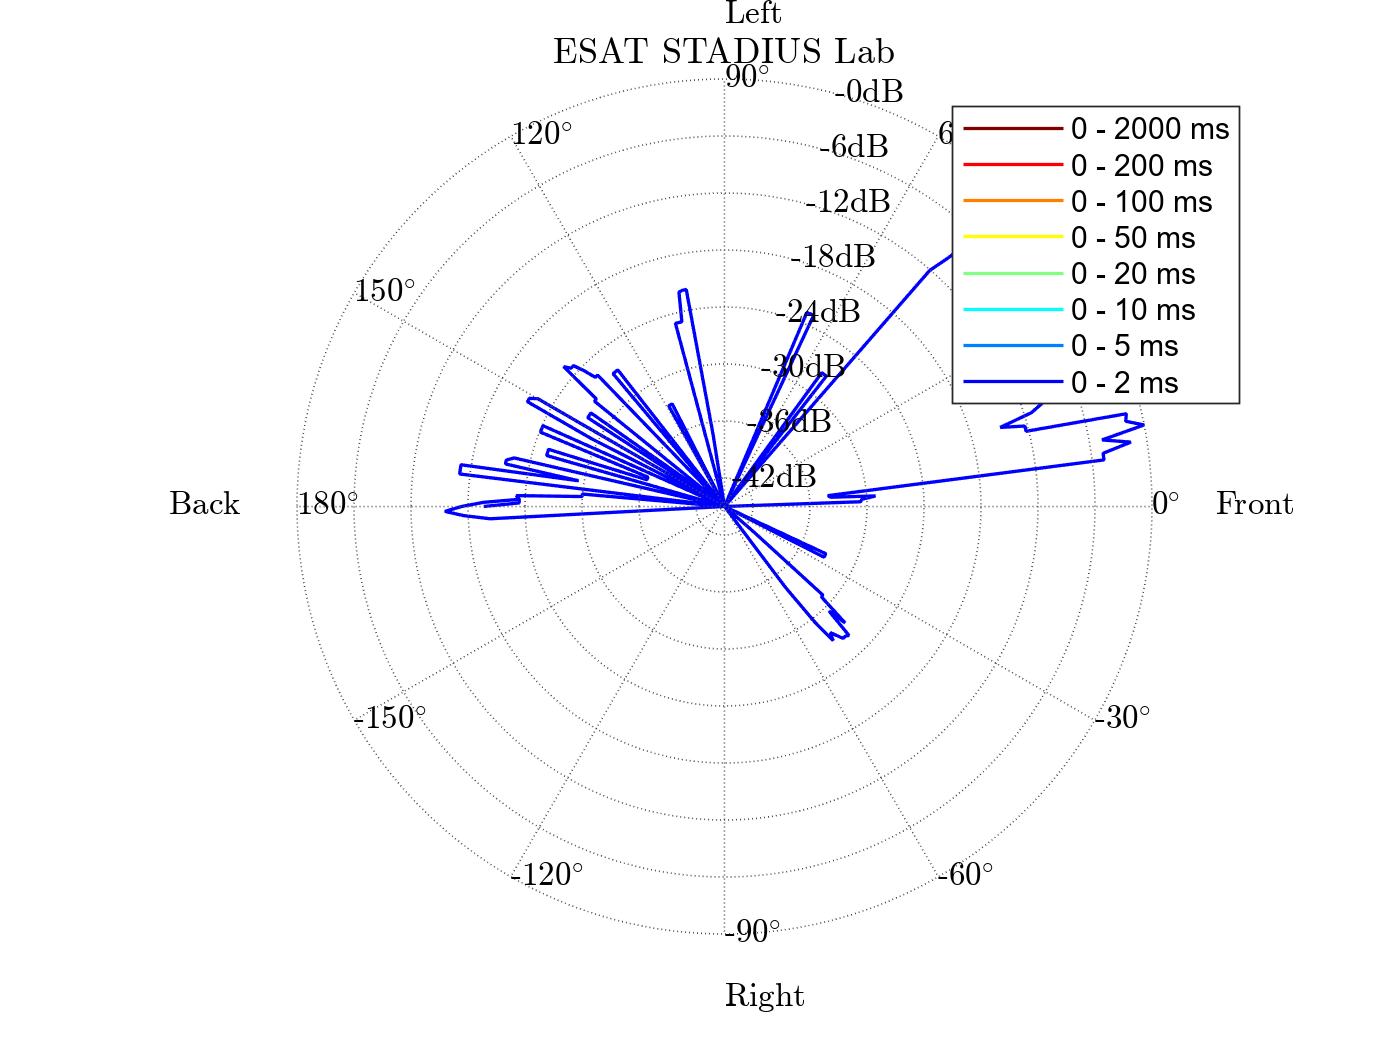

Ended spatio-temporal visualization in 0.35173 seconds.


ans = -12

% Interpolated
spatioTemporalVisualization(P_inter, DOA_inter, v)

Started spatio-temporal visualization.


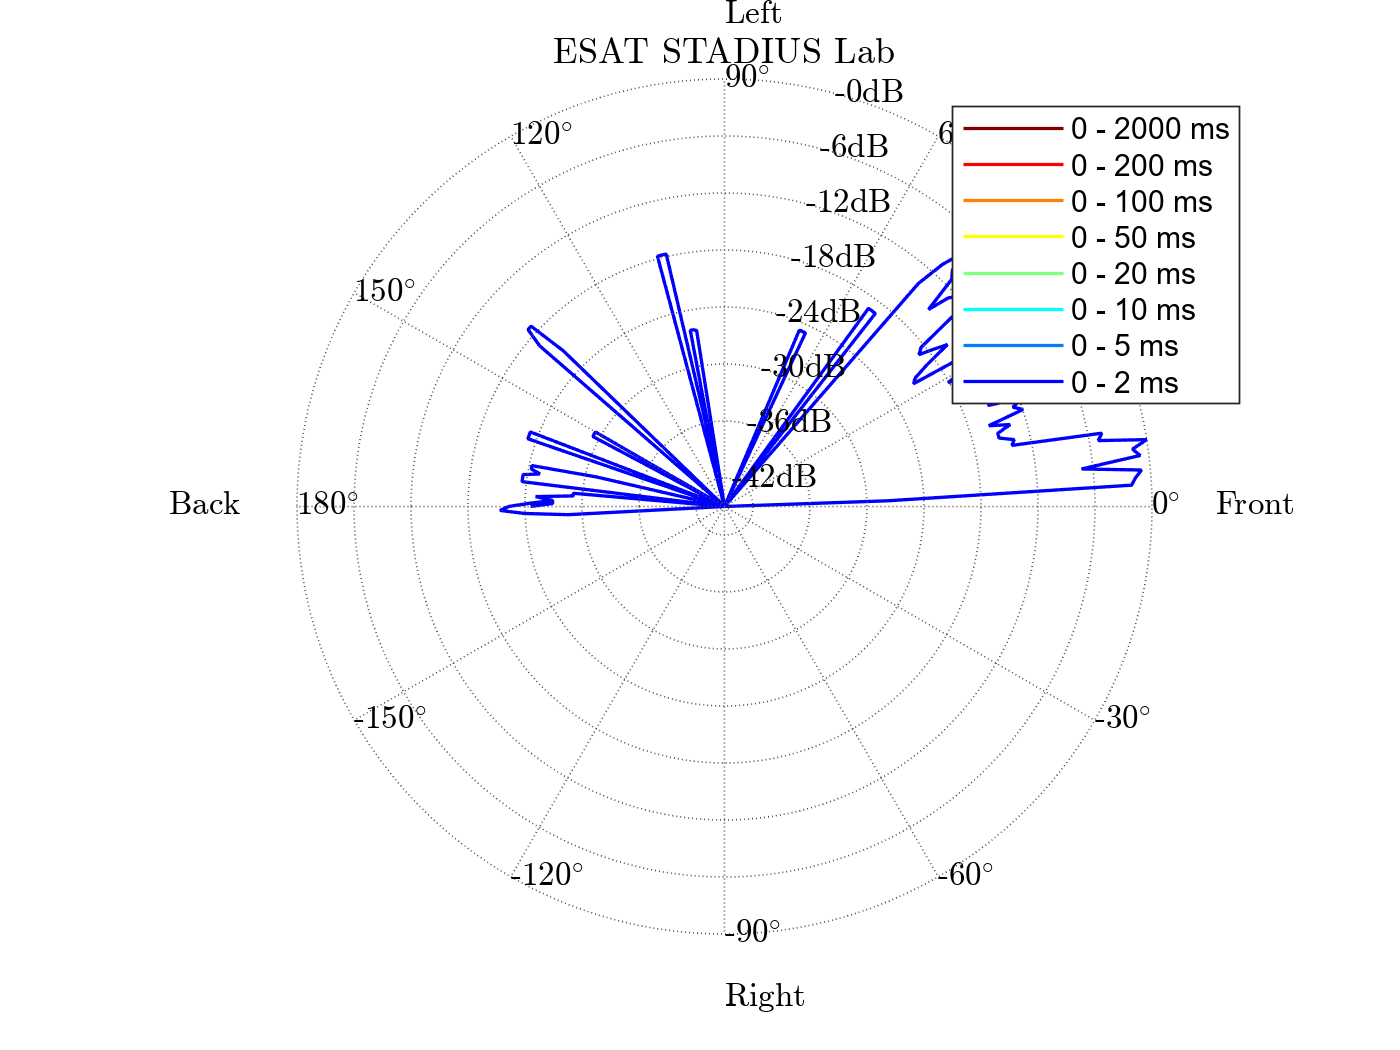

Ended spatio-temporal visualization in 0.35447 seconds.


ans = -10

spatioTemporalVisualization(P_pos_inter, DOA_inter, v)

Started spatio-temporal visualization.


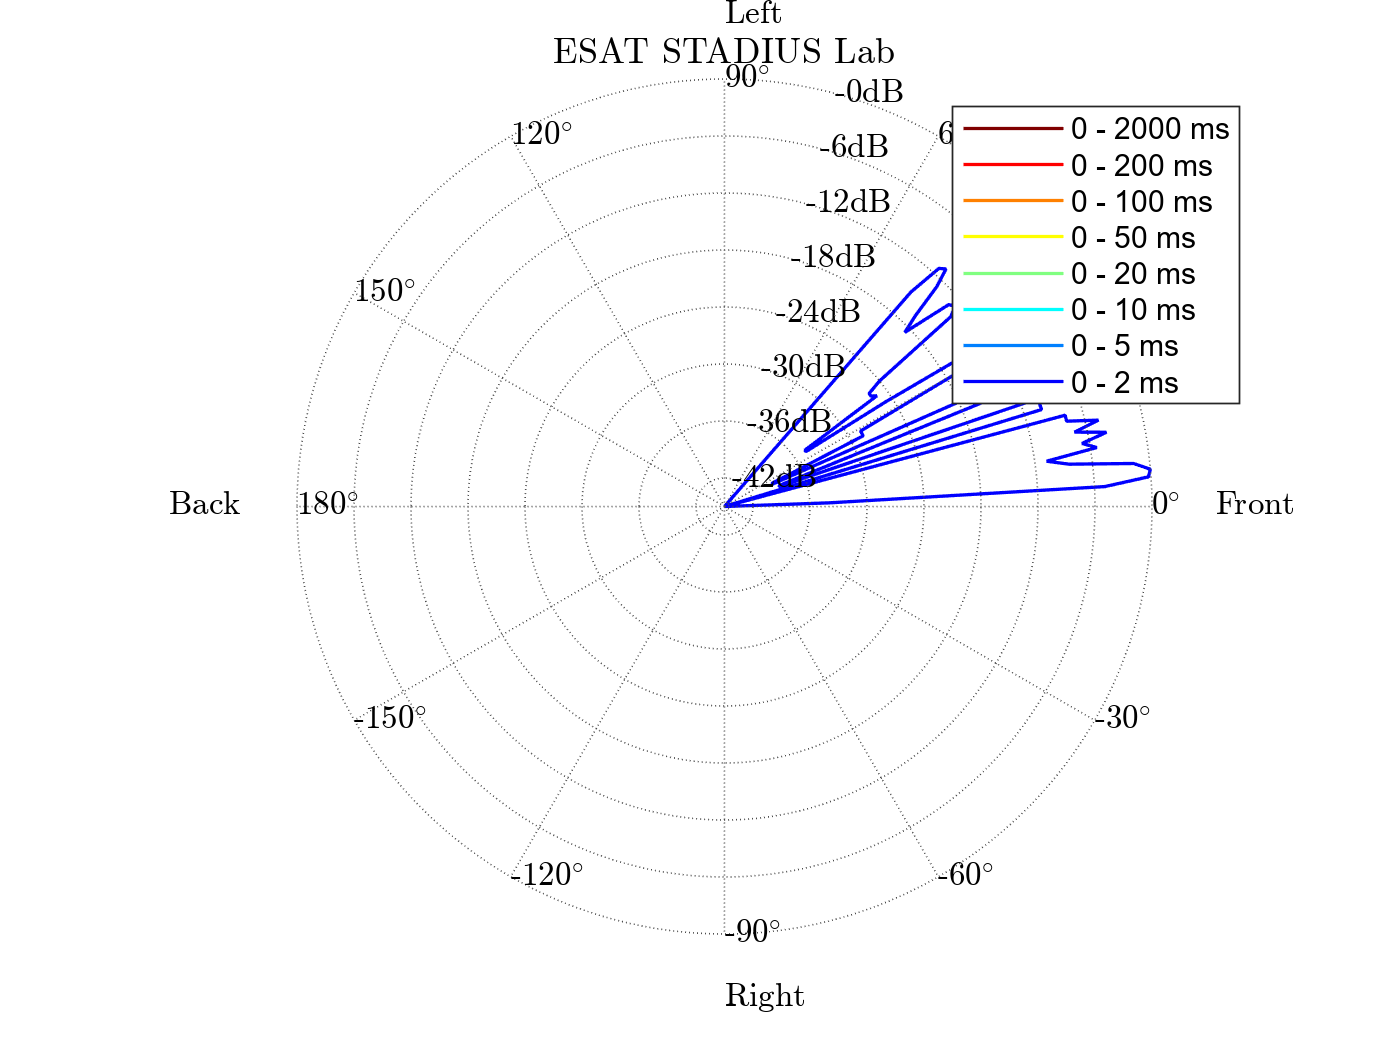

Ended spatio-temporal visualization in 0.42133 seconds.


ans = -6

spatioTemporalVisualization(P_neg_inter, DOA_inter, v)

Started spatio-temporal visualization.


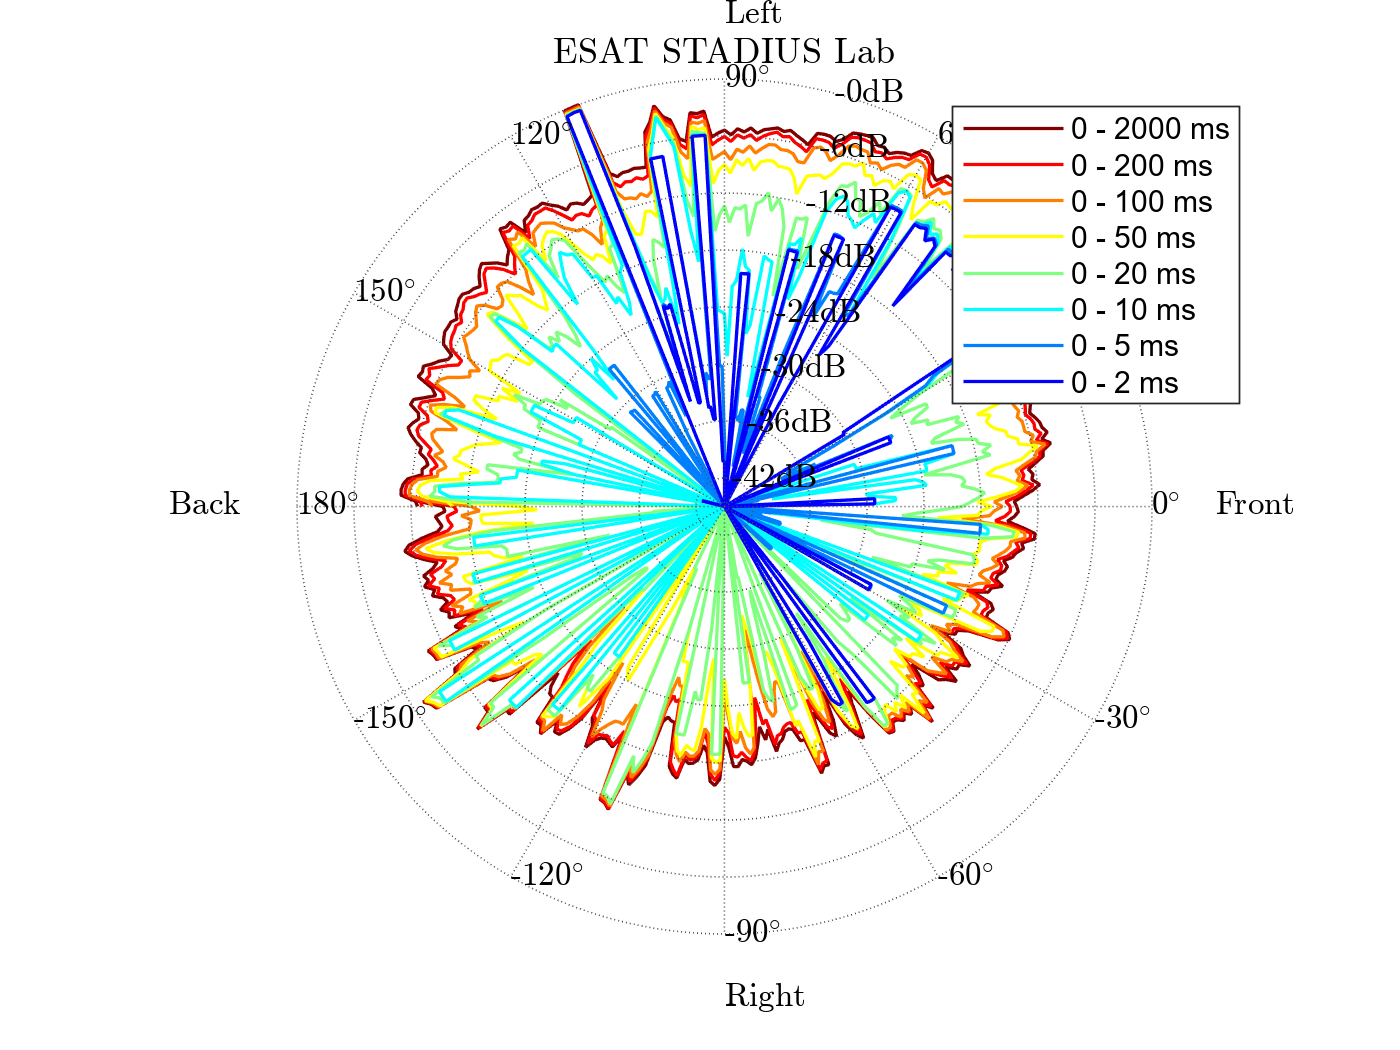

Ended spatio-temporal visualization in 0.48278 seconds.


ans = -111

% Third measurement
spatioTemporalVisualization(P_third, DOA_third, v)

Started spatio-temporal visualization.


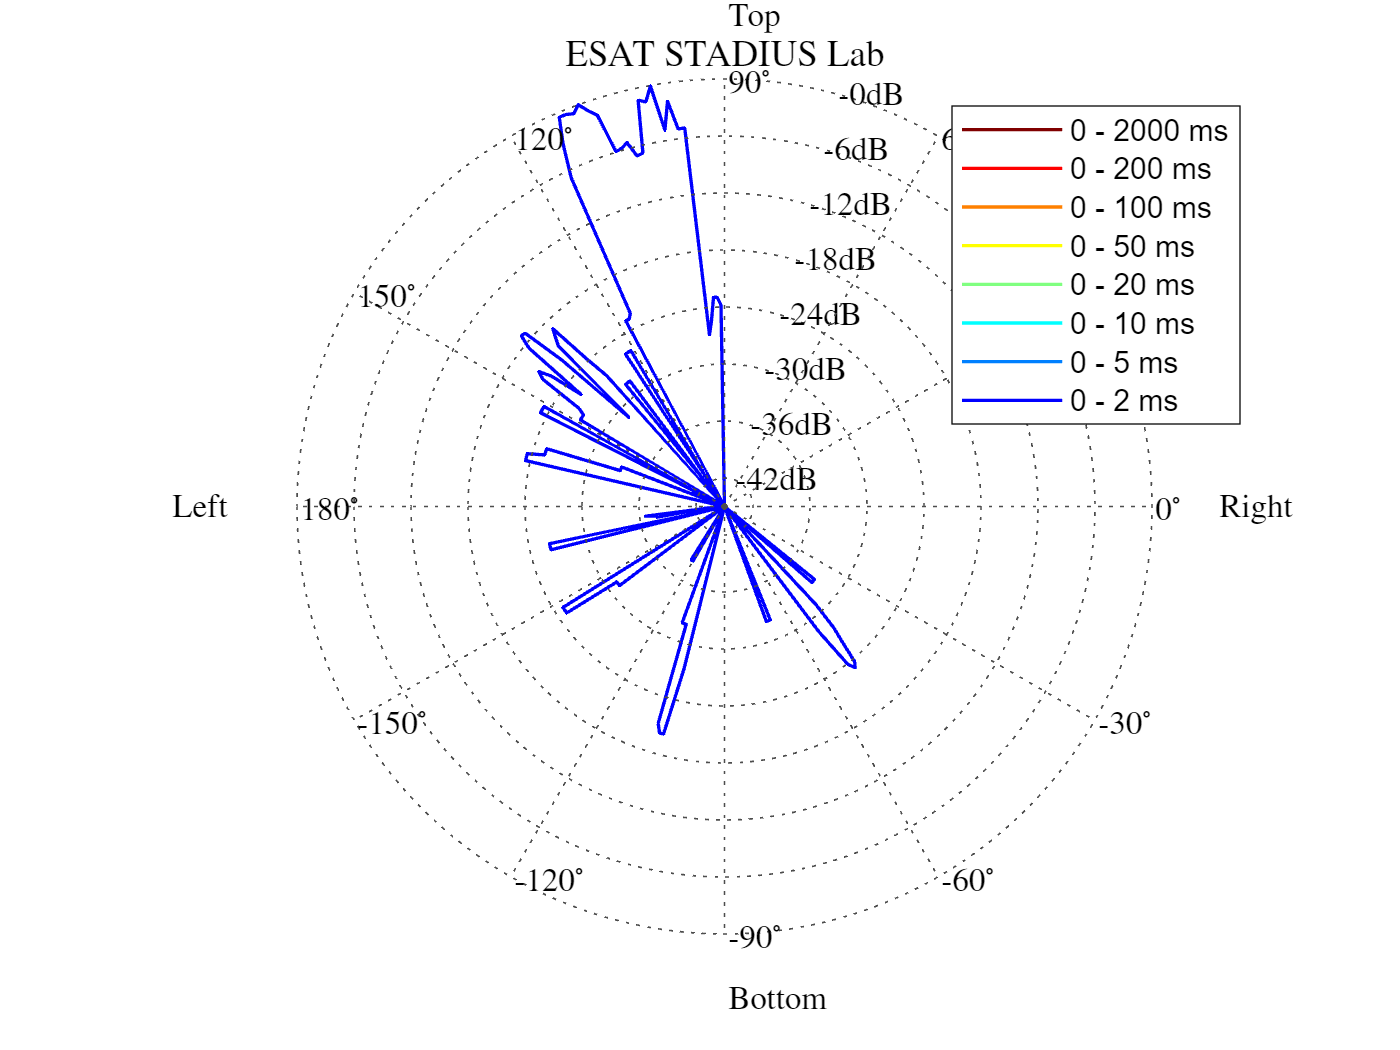

Ended spatio-temporal visualization in 0.29693 seconds.


ans = -111

v.plane = 'transverse';
% Interpolated
spatioTemporalVisualization(P_inter, DOA_inter, v)

Started spatio-temporal visualization.


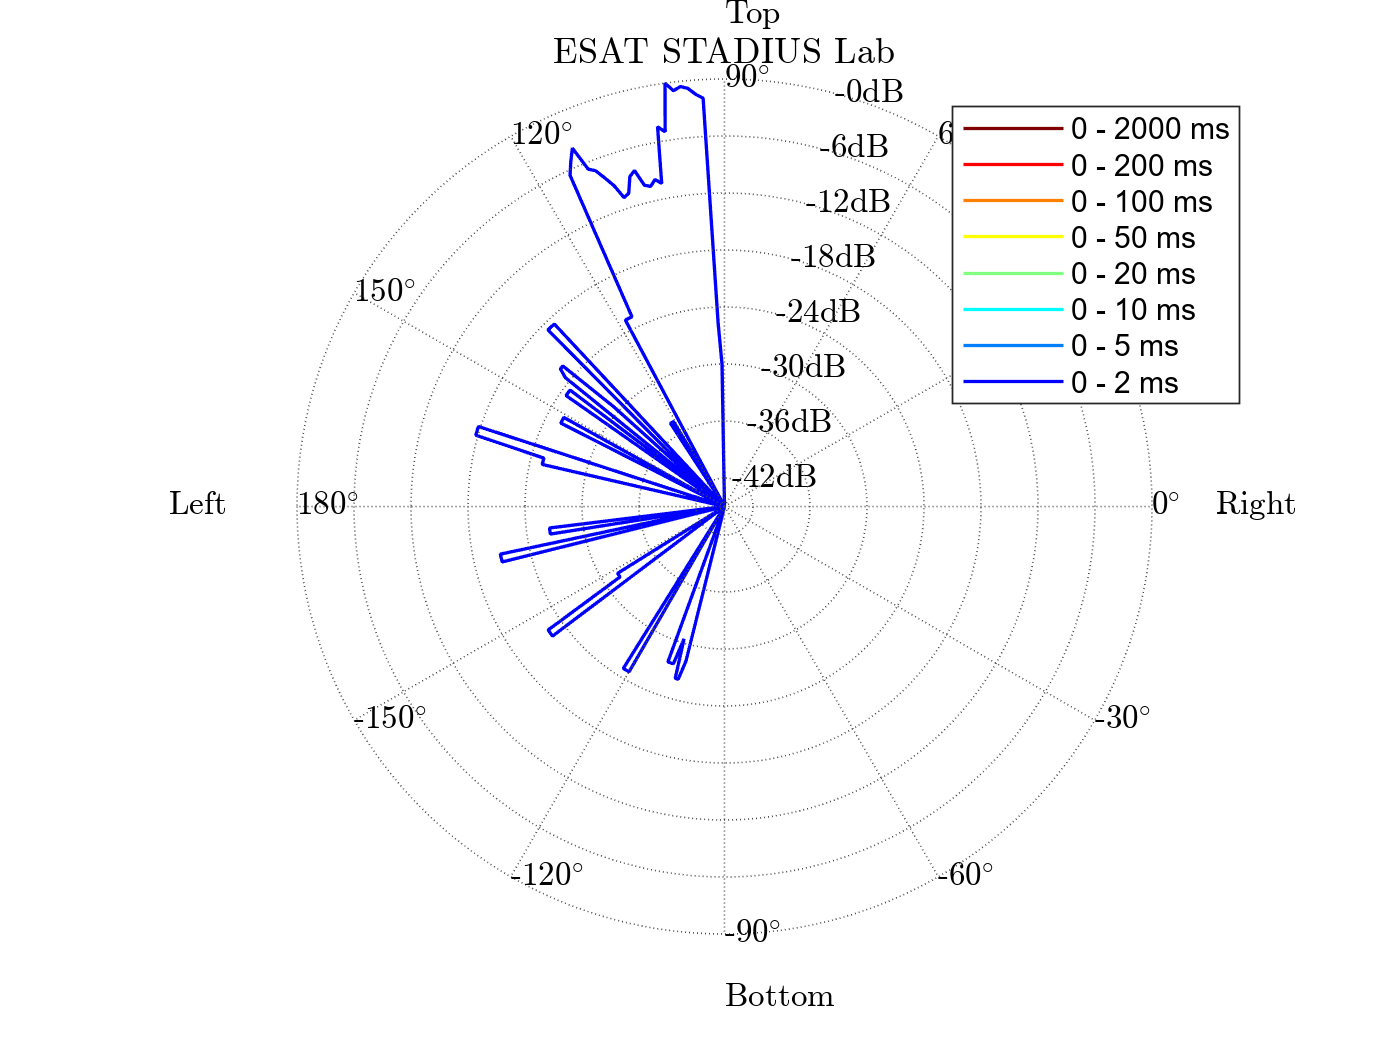

Ended spatio-temporal visualization in 0.27742 seconds.


ans = -99

spatioTemporalVisualization(P_pos_inter, DOA_inter, v)

Started spatio-temporal visualization.


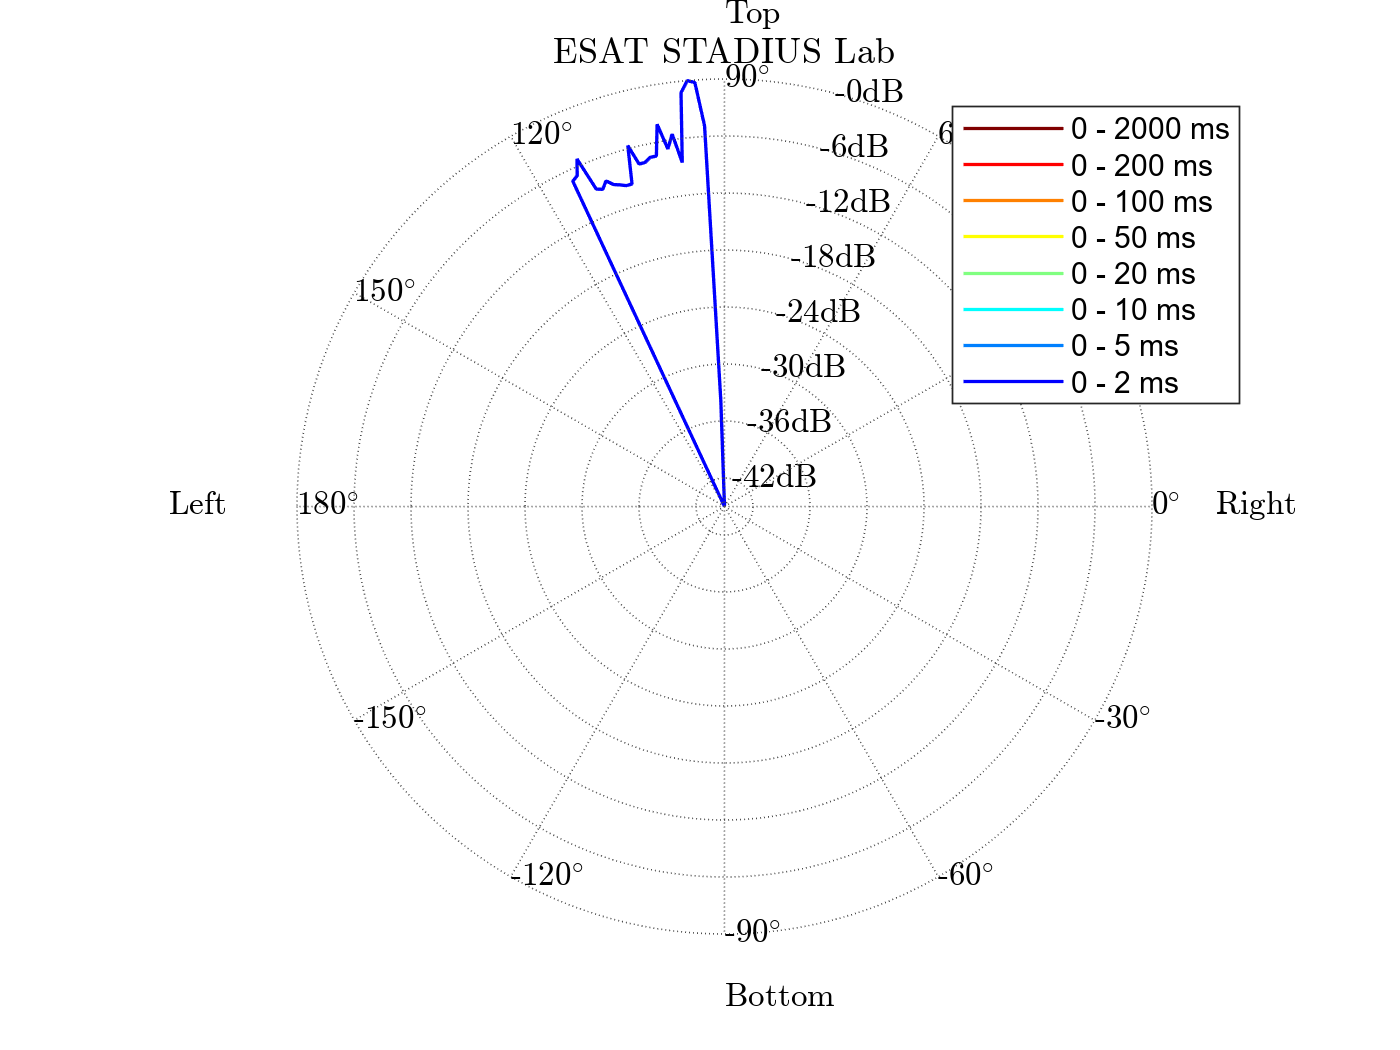

Ended spatio-temporal visualization in 0.30158 seconds.


ans = -96

spatioTemporalVisualization(P_neg_inter, DOA_inter, v)

Started spatio-temporal visualization.


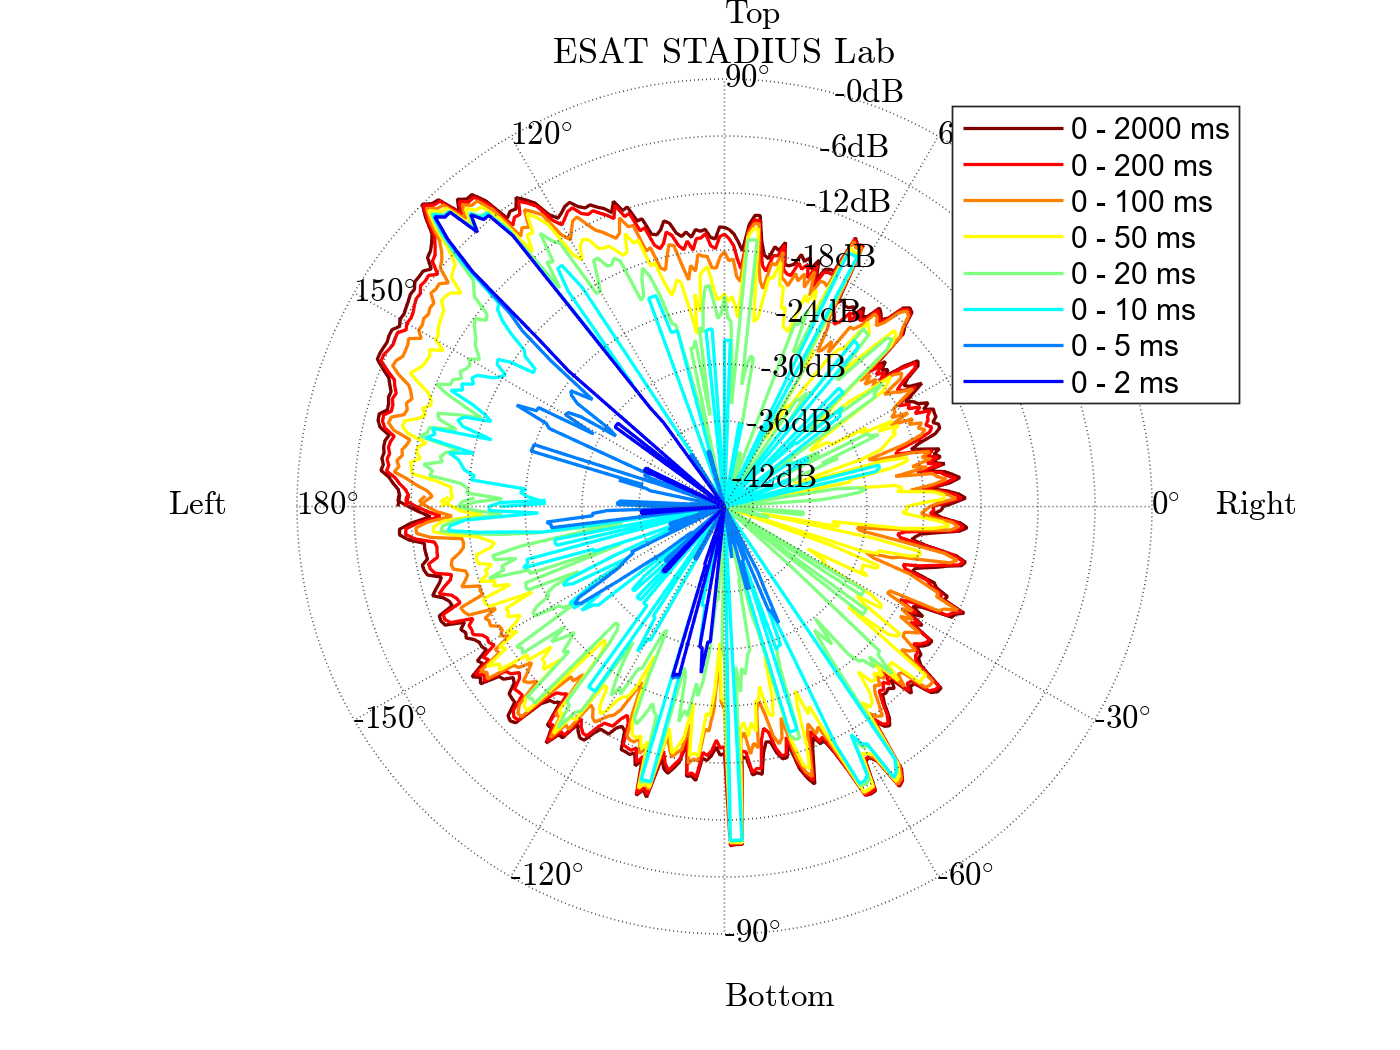

Ended spatio-temporal visualization in 0.34943 seconds.


ans = -136

% Original
spatioTemporalVisualization(P_original, DOA_original, v)

Started spatio-temporal visualization.


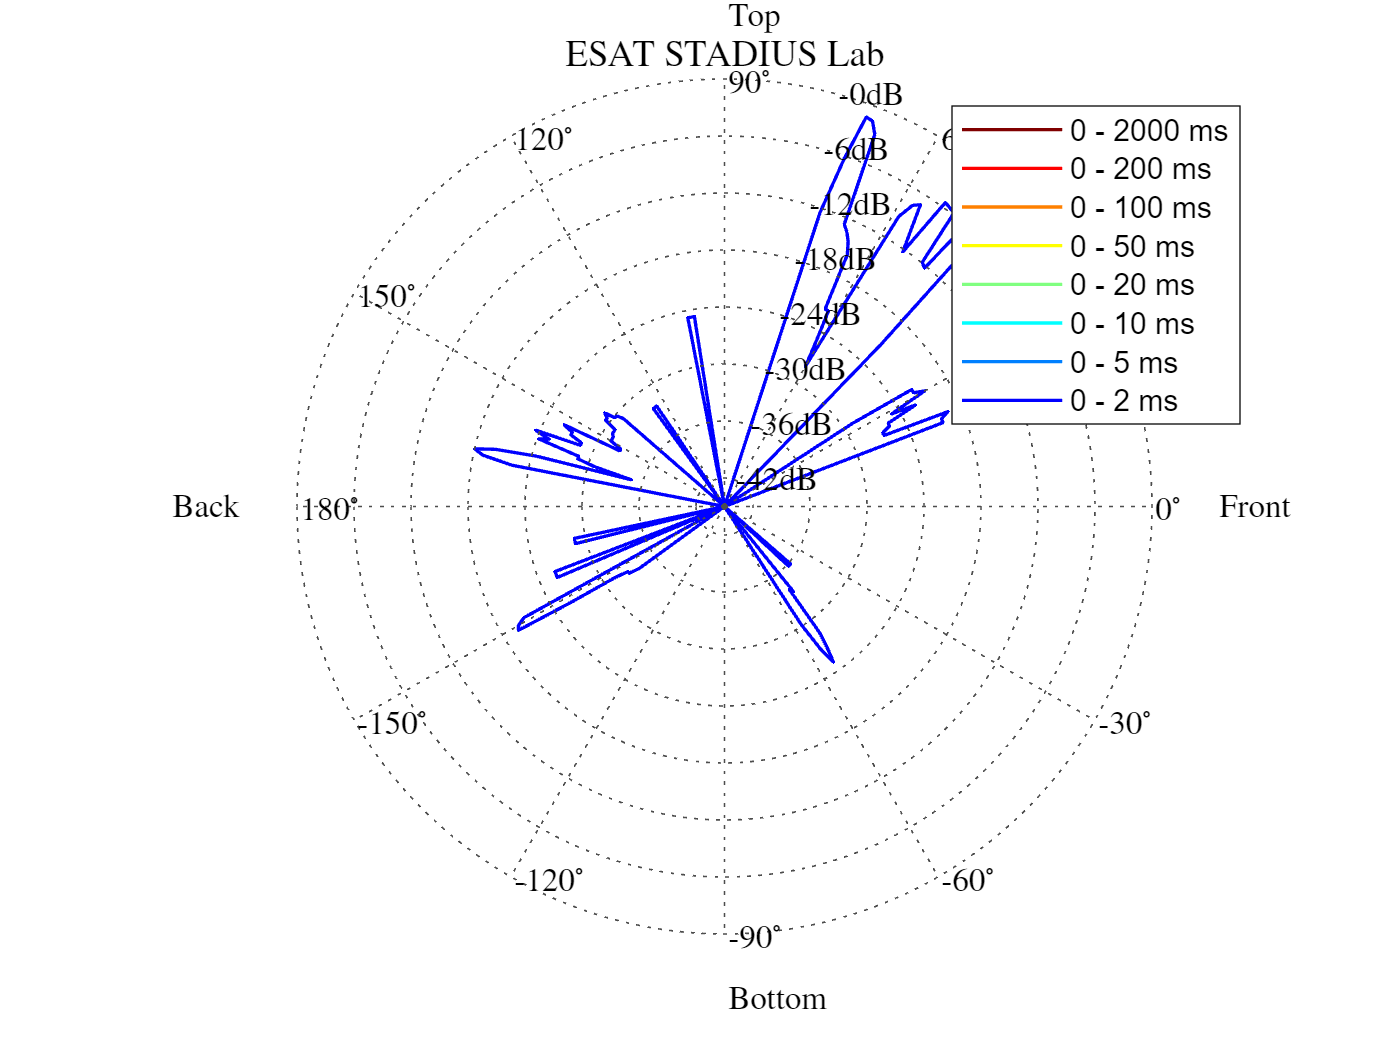

Ended spatio-temporal visualization in 0.34289 seconds.


ans = -50

v.plane = 'median';
% Interpolated
spatioTemporalVisualization(P_inter, DOA_inter, v)

Started spatio-temporal visualization.


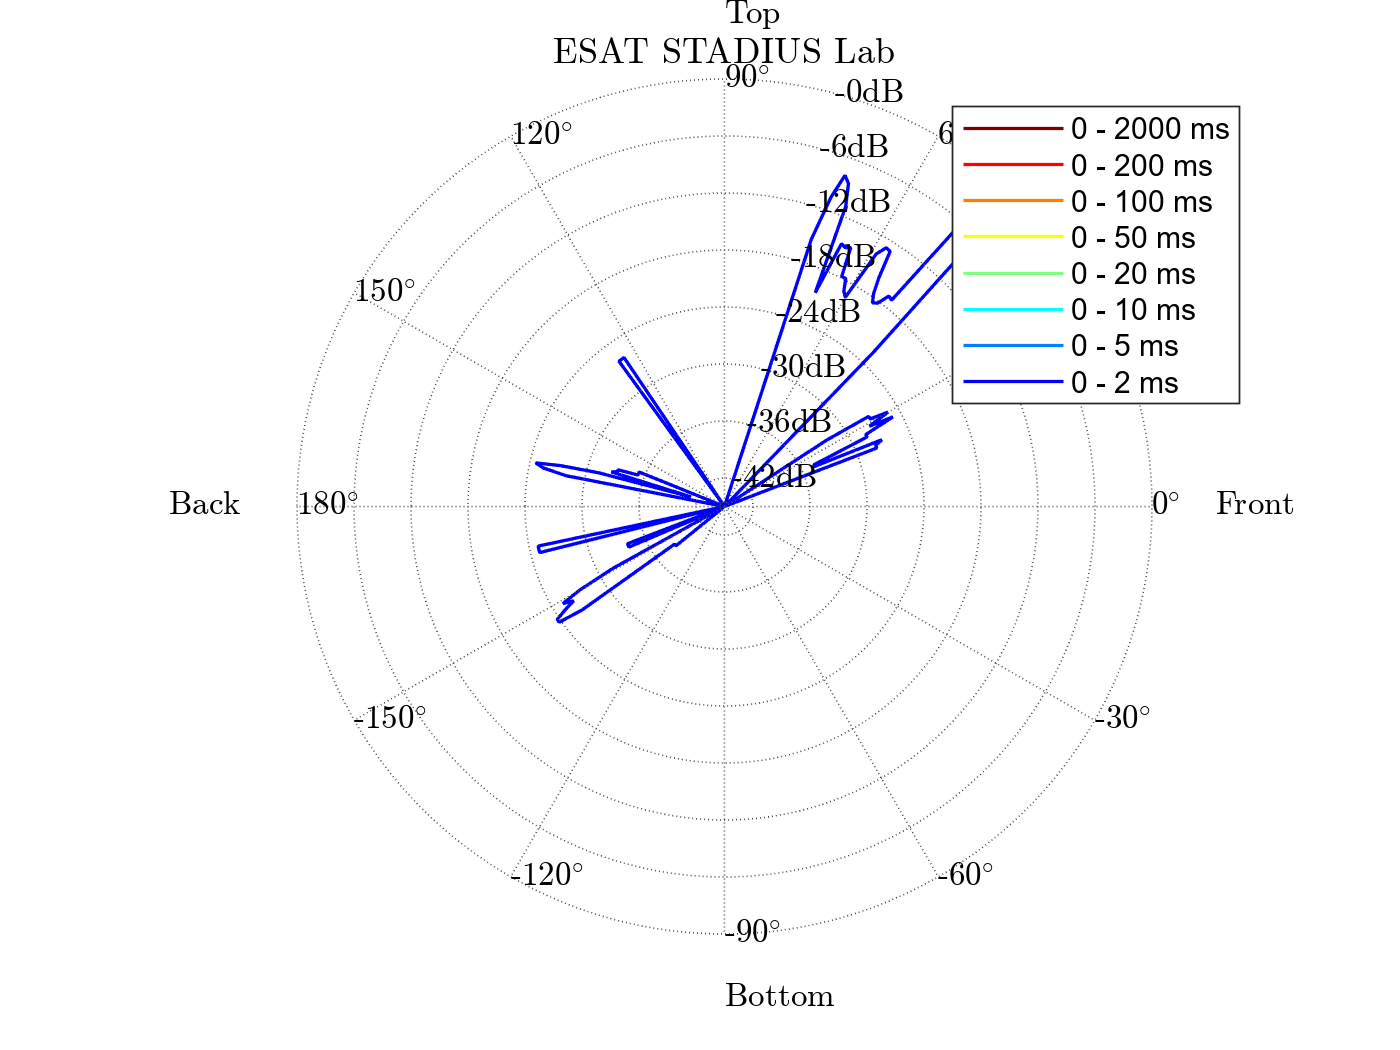

Ended spatio-temporal visualization in 0.25974 seconds.


ans = -50

spatioTemporalVisualization(P_pos_inter, DOA_inter, v)

Started spatio-temporal visualization.


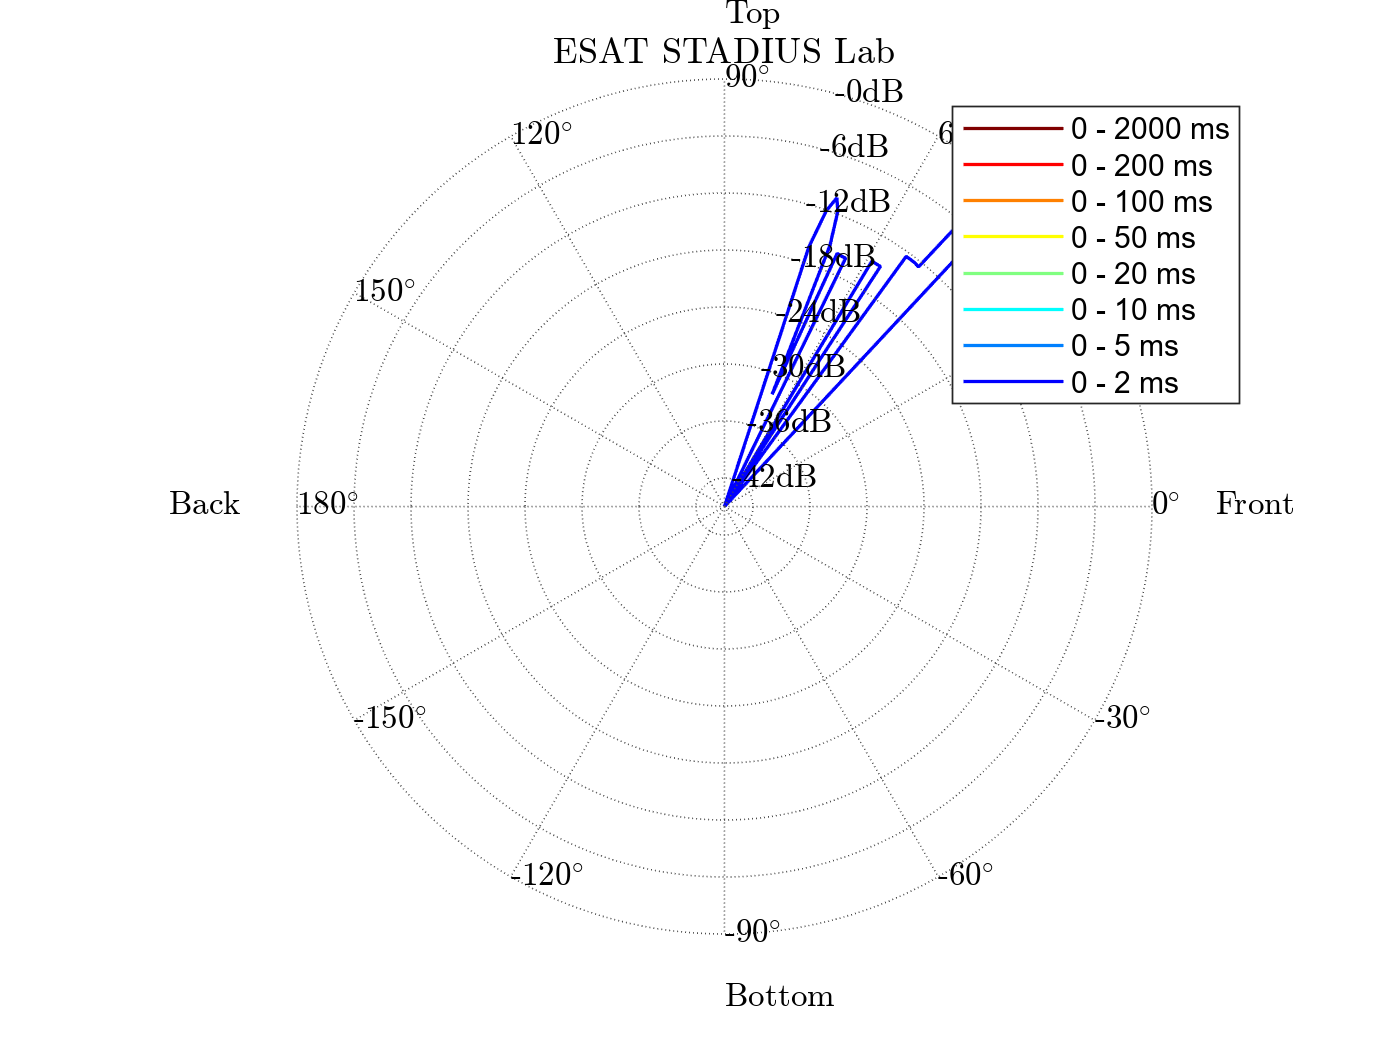

Ended spatio-temporal visualization in 0.30021 seconds.


ans = -50

spatioTemporalVisualization(P_neg_inter, DOA_inter, v)

Started spatio-temporal visualization.


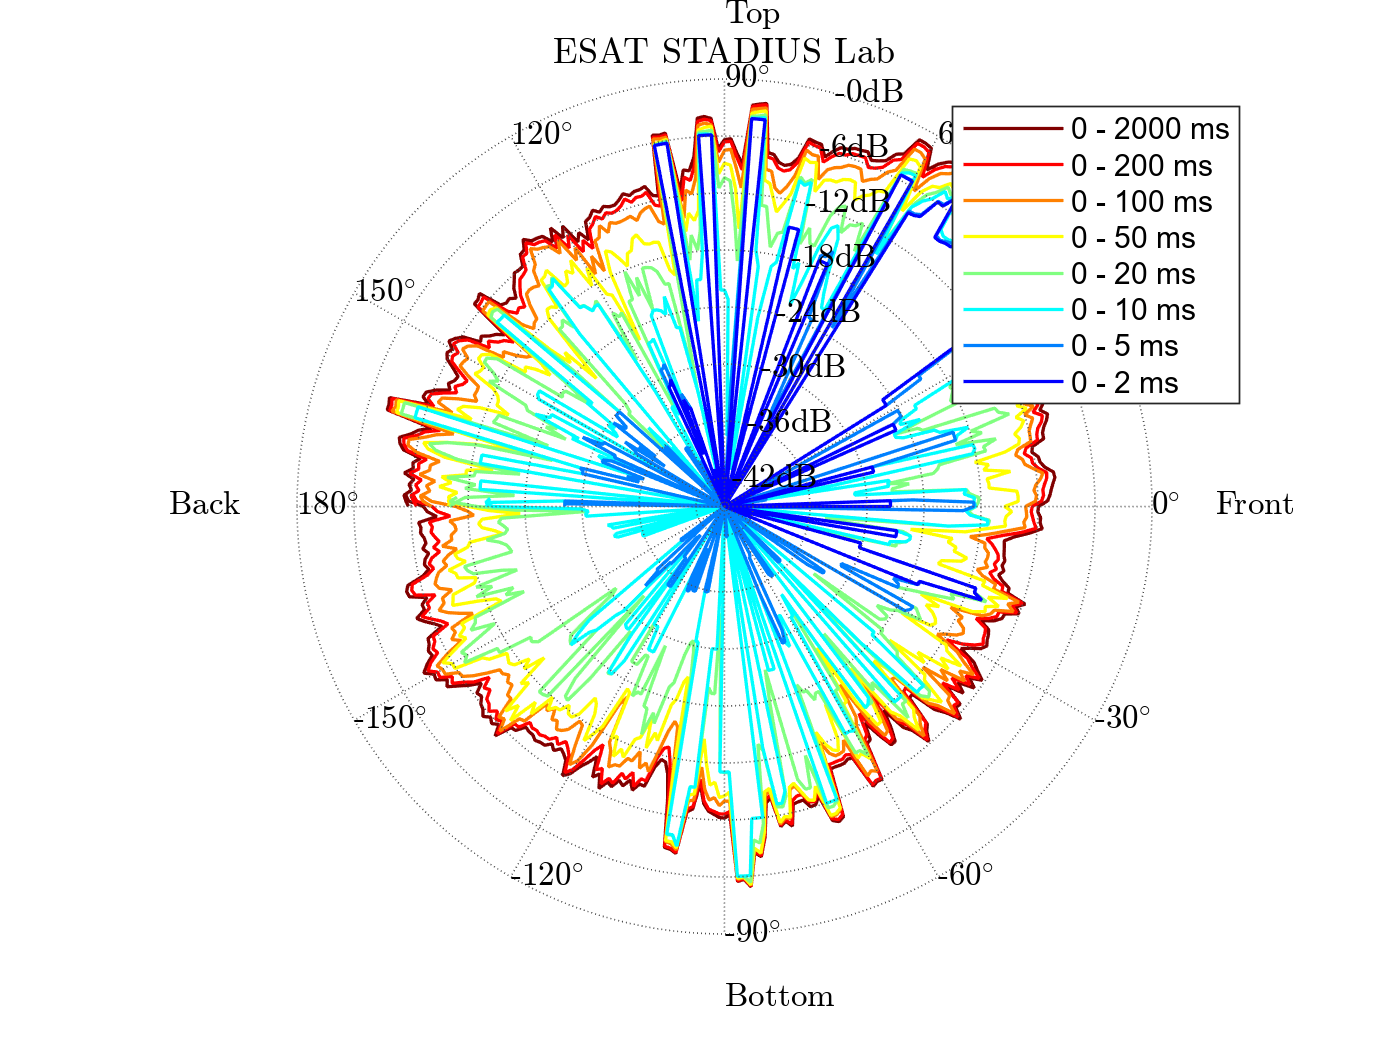

Ended spatio-temporal visualization in 0.31365 seconds.


ans = -85

% Original
spatioTemporalVisualization(P_original, DOA_original, v)